# single points

filename = "Unicorn_CSA_RevA-COB_woShiled_Gain101_20260829/Unicorn_CSA_RevA-COB_wo_Shield_Gain101_2026-08-29 (1).tdms";

[x, Fs] = read_tdms_waveform(filename);
x = x - mean(x);

N = numel(x);


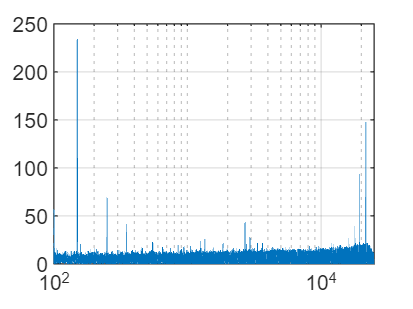

N_FFT = 1E6;
x_cut = x(1:N_FFT);
[psdV2PerHz, frequencyHz] = ...
    periodogram(x_cut, [], N_FFT, Fs, "onesided");

figure
semilogx(frequencyHz, sqrt(psdV2PerHz)./101*1E9);
box on;
grid on;
xlim([100,25E3])

N_cut = 1.2E6;
N_FFT = 1E5;
N_rep = 10;
X_array = zeros(N_cut, N_rep);
for i = 1:N_rep
    fileName = sprintf( ...
    "Unicorn_CSA_RevA-COB_woShiled_Gain101_20260829/Unicorn_CSA_RevA-COB_wo_Shield_Gain101_2026-08-29 (%d).tdms", ...
    i);
    [x_temp, Fs] = read_tdms_waveform(fileName);
    x_temp = x_temp(1:N_cut);
    X_array(:, i) = x_temp;
end


X_sq = reshape(X_array, [N_FFT, N_rep*N_cut/N_FFT]);
X_sq = X_sq - mean(X_sq);
psdV2PerHz_array = zeros(N_FFT/2+1, N_rep*N_cut/N_FFT);
window = hamming(N_FFT, "periodic");
for i = 1:N_rep*N_cut/N_FFT
    [psdV2PerHz_temp, frequencyHz_temp] = ...
    periodogram(X_sq(:,i), window, N_FFT, Fs, "onesided");
    psdV2PerHz_array(:,i) = psdV2PerHz_temp;
    fprintf("[%d/%d] finished!\n", i, N_rep*N_cut/N_FFT);
end

[1/120] finished!
[2/120] finished!
[3/120] finished!
[4/120] finished!
[5/120] finished!
[6/120] finished!
[7/120] finished!
[8/120] finished!
[9/120] finished!
[10/120] finished!
[11/120] finished!
[12/120] finished!
[13/120] finished!
[14/120] finished!
[15/120] finished!
[16/120] finished!
[17/120] finished!
[18/120] finished!
[19/120] finished!
[20/120] finished!
[21/120] finished!
[22/120] finished!
[23/120] finished!
[24/120] finished!
[25/120] finished!
[26/120] finished!
[27/120] finished!
[28/120] finished!
[29/120] finished!
[30/120] finished!
[31/120] finished!
[32/120] finished!
[33/120] finished!
[34/120] finished!
[35/120] finished!
[36/120] finished!
[37/120] finished!
[38/120] finished!
[39/120] finished!
[40/120] finished!
[41/120] finished!
[42/120] finished!
[43/120] finished!
[44/120] finished!
[45/120] finished!
[46/120] finished!
[47/120] finished!
[48/120] finished!
[49/120] finished!
[50/120] finished!
[51/120] finished!
[52/120] finished!
[53/120] finished!
[5

## plot results

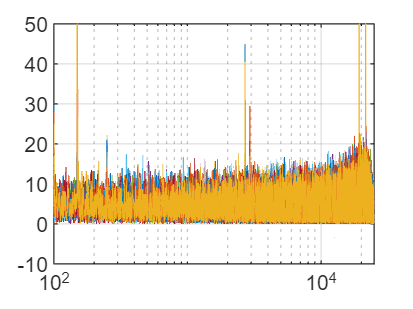

figure
semilogx(frequencyHz_temp,sqrt(psdV2PerHz_array(:,1:10))./101*1E9)
xlim([100, 25E3]);
ylim([-10, 50])
box on;
grid on;

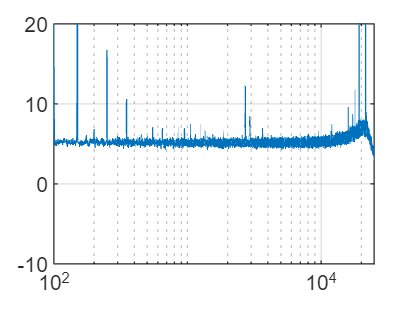

figure
semilogx(frequencyHz_temp, sqrt(mean(psdV2PerHz_array,2))./101.*1E9);
xlim([100, 25E3]);
ylim([-10, 20])
box on;
grid on;